syms t
syms A
syms t_u

s = piecewise(0<=t<=t_u, A*(1- ((2*t-t_u)/(t_u))^2), t<0,0,t>t_u,0)

$$s = \left\{ \begin{array}{cl} -A\,\left(\frac{{\left(2\,t-t_{u}\right)}^{2}}{{t_{u}}^{2}}-1\right) & \text{ if }t\leq t_{u}\wedge 0\leq t\\ 0 & \text{ if }t_{u}<t\vee t<0 \end{array}\right.$$

%plot s

s_plot = subs(s,A,sym(1));
s_plot = subs(s_plot,t_u,sym(10));


t_range = 0:0.1:10;

s_plot = subs(s_plot,t,t_range)

$$s\_plot = \left(\begin{array}{ccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccc} 0 & \frac{99}{2500} & \frac{49}{625} & \frac{291}{2500} & \frac{96}{625} & \frac{19}{100} & \frac{141}{625} & \frac{651}{2500} & \frac{184}{625} & \frac{819}{2500} & \frac{9}{25} & \frac{979}{2500} & \frac{264}{625} & \frac{1131}{2500} & \frac{301}{625} & \frac{51}{100} & \frac{336}{625} & \frac{1411}{2500} & \frac{369}{625} & \frac{1539}{2500} & \frac{16}{25} & \frac{1659}{2500} & \frac{429}{625} & \frac{1771}{2500} & \frac{456}{625} & \frac{3}{4} & \frac{481}{625} & \frac{1971}{2500} & \frac{504}{625} & \frac{2059}{2500} & \frac{21}{25} & \frac{2139}{2500} & \frac{544}{625} & \frac{2211}{2500} & \frac{561}{625} & \frac{91}{100} & \frac{576}{625} & \frac{2331}{2500} & \frac{589}{625} & \frac{2379}{2500} & \frac{24}{25} & \frac{2419}{2500} & \frac{609}{625} & \frac{2451}{2500} & \frac{616}{625} & \frac{99}{100} & \frac{621}{625} & \frac{2491}{2500} & \frac{624}{625} & \frac{2499}{2500} & 1 & \frac{2499}{2500} & \frac{624}{625} & \frac{2491}{2500} & \frac{621}{625} & \frac{99}{100} & \frac{616}{625} & \frac{2451}{2500} & \frac{609}{625} & \frac{2419}{2500} & \frac{24}{25} & \frac{2379}{2500} & \frac{589}{625} & \frac{2331}{2500} & \frac{576}{625} & \frac{91}{100} & \frac{561}{625} & \frac{2211}{2500} & \frac{544}{625} & \frac{2139}{2500} & \frac{21}{25} & \frac{2059}{2500} & \frac{504}{625} & \frac{1971}{2500} & \frac{481}{625} & \frac{3}{4} & \frac{456}{625} & \frac{1771}{2500} & \frac{429}{625} & \frac{1659}{2500} & \frac{16}{25} & \frac{1539}{2500} & \frac{369}{625} & \frac{1411}{2500} & \frac{336}{625} & \frac{51}{100} & \frac{301}{625} & \frac{1131}{2500} & \frac{264}{625} & \frac{979}{2500} & \frac{9}{25} & \frac{819}{2500} & \frac{184}{625} & \frac{651}{2500} & \frac{141}{625} & \frac{19}{100} & \frac{96}{625} & \frac{291}{2500} & \frac{49}{625} & \frac{99}{2500} & 0 \end{array}\right)$$

s_plot = double(s_plot)

s_plot =          0    0.0396    0.0784    0.1164    0.1536    0.1900    0.2256    0.2604    0.2944    0.3276    0.3600    0.3916    0.4224    0.4524    0.4816    0.5100    0.5376    0.5644    0.5904    0.6156    0.6400    0.6636    0.6864    0.7084    0.7296    0.7500    0.7696    0.7884    0.8064    0.8236    0.8400    0.8556    0.8704    0.8844    0.8976    0.9100    0.9216    0.9324    0.9424    0.9516    0.9600    0.9676    0.9744    0.9804    0.9856    0.9900    0.9936    0.9964    0.9984    0.9996


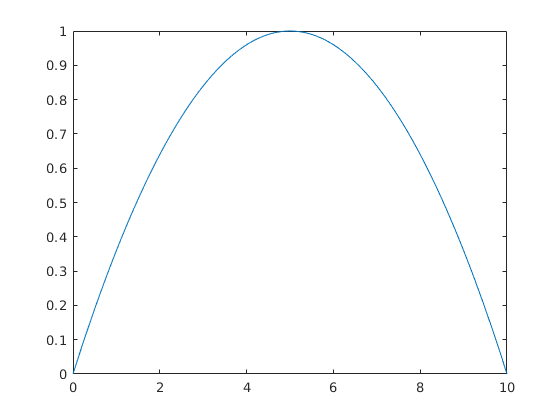


plot(t_range,s_plot)


%s1  =piecewise(-t_u/2<=t<=t_u/2, A*(1- ((2*t)/(t_u))^2), t<-t_u/2,0,t>t_u/2,0)
s1  =piecewise(-t_u/2<=t<=t_u/2, A, t<-t_u/2,0,t>t_u/2,0)

$$s1 = \left\{ \begin{array}{cl} A & \text{ if }0\leq 2\,t+t_{u}\wedge 2\,t\leq t_{u}\\ 0 & \text{ if }t<-\frac{t_{u}}{2}\vee \frac{t_{u}}{2}<t \end{array}\right.$$

%plot s1

s_plot = subs(s1,A,sym(1));
s_plot = subs(s_plot,t_u,sym(10));


t_range = -10:0.1:10;

s_plot = subs(s_plot,t,t_range)

$$s\_plot = \left(\begin{array}{ccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

s_plot = double(s_plot)

s_plot =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


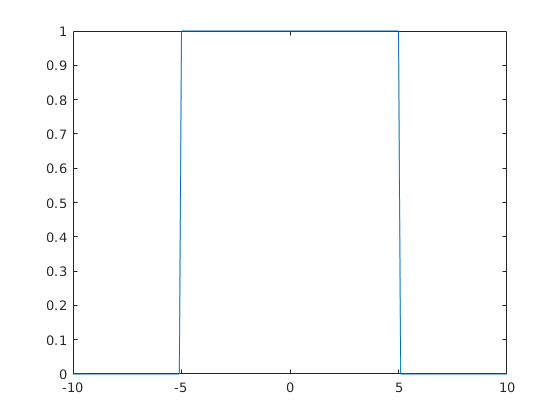



plot(t_range,s_plot)

syms f

S1 = 2*int(s1*cos(2*pi*f *t),t,0,t_u/2)

$$S1 = \left\{ \begin{array}{cl} 0 & \text{ if }t_{u}=0\\ \frac{A\,\sin\left(\pi \,f\,t_{u}\right)}{f\,\pi } & \text{ if }t_{u}\neq 0 \end{array}\right.$$

simplify(S1)

$$ans = \frac{A\,\sin\left(\pi \,f\,t_{u}\right)}{f\,\pi }$$

%plot S1

S_plot = subs(S1,A,sym(1))

$$S\_plot = \left\{ \begin{array}{cl} 0 & \text{ if }t_{u}=0\\ \frac{\sin\left(\pi \,f\,t_{u}\right)}{f\,\pi } & \text{ if }t_{u}\neq 0 \end{array}\right.$$

S_plot = subs(S_plot,t_u,sym(10))

$$S\_plot = \frac{\sin\left(10\,\pi \,f\right)}{f\,\pi }$$

symvar(S_plot)

$$ans = f$$


f_range = -10.005:0.01:10.005

f_range =   -10.0050   -9.9950   -9.9850   -9.9750   -9.9650   -9.9550   -9.9450   -9.9350   -9.9250   -9.9150   -9.9050   -9.8950   -9.8850   -9.8750   -9.8650   -9.8550   -9.8450   -9.8350   -9.8250   -9.8150   -9.8050   -9.7950   -9.7850   -9.7750   -9.7650   -9.7550   -9.7450   -9.7350   -9.7250   -9.7150   -9.7050   -9.6950   -9.6850   -9.6750   -9.6650   -9.6550   -9.6450   -9.6350   -9.6250   -9.6150   -9.6050   -9.5950   -9.5850   -9.5750   -9.5650   -9.5550   -9.5450   -9.5350   -9.5250   -9.5150



S_plot = subs(S_plot,symvar(S_plot),f_range)

S_plot = log10(double(S_plot)).^2

S_plot =    5.3040 + 0.0000i   3.4404 - 6.2832i   1.5221 - 5.0194i   0.8497 - 4.4931i   0.5278 - 4.2180i   0.3902 - 4.0947i   0.3889 - 4.0935i   0.5238 - 4.2144i   0.8425 - 4.4871i   1.5108 - 5.0111i   3.4224 - 6.2725i   5.2819 + 0.0000i   3.3675 + 0.0000i   2.6968 + 0.0000i   2.3758 + 0.0000i   2.2386 + 0.0000i   2.2373 + 0.0000i   2.3717 + 0.0000i   2.6896 + 0.0000i   3.3562 + 0.0000i   5.2637 + 0.0000i   3.4001 - 6.2593i   1.4898 - 4.9954i   0.8208 - 4.4691i   0.5007 - 4.1939i   0.3638 - 4.0706i   0.3625 - 4.0694i   0.4966 - 4.1903i   0.8135 - 4.4630i   1.4784 - 4.9869i   3.3817 - 6.2483i   5.2412 + 0.0000i   3.3350 + 0.0000i   2.6677 + 0.0000i   2.3485 + 0.0000i   2.2120 + 0.0000i   2.2107 + 0.0000i   2.3443 + 0.0000i   2.6604 + 0.0000i   3.3235 + 0.0000i   5.2227 + 0.0000i   3.3591 - 6.2348i   1.4571 - 4.9710i   0.7915 - 4.4446i   0.4731 - 4.1694i   0.3371 - 4.0461i   0.3357 - 4.0448i   0.4690 - 4.1657i   0.7841 - 4.4384i   1.4455 - 4.9623i


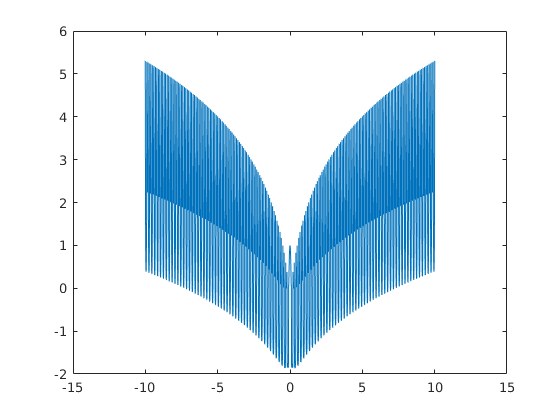



plot(f_range,S_plot)